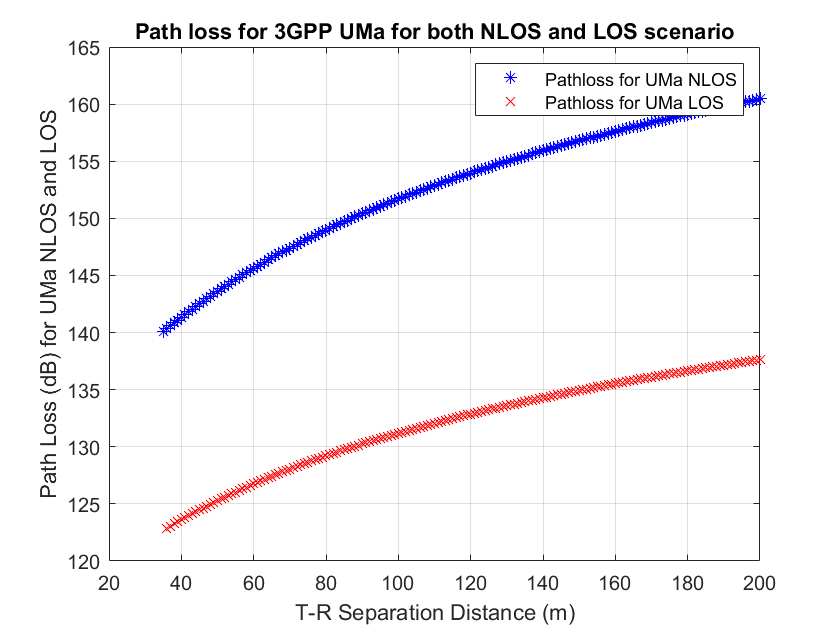

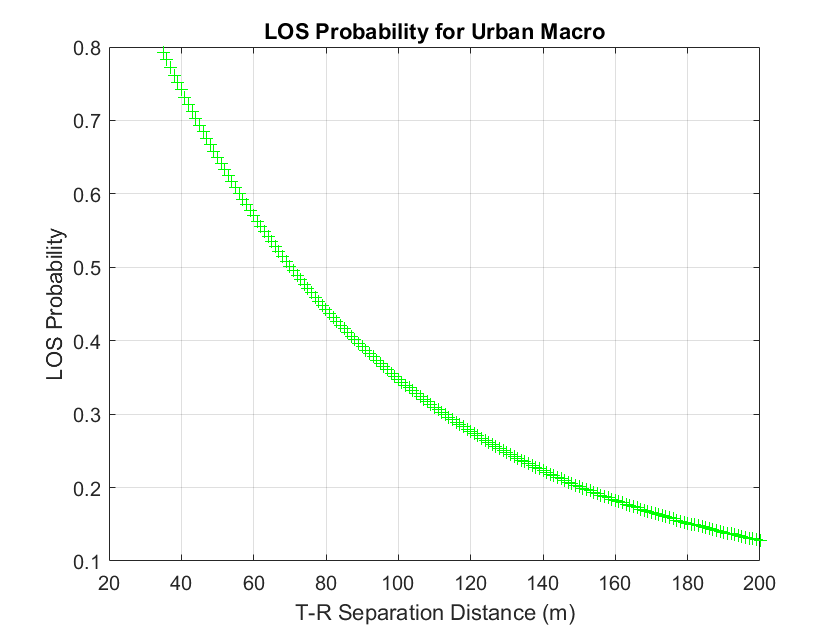

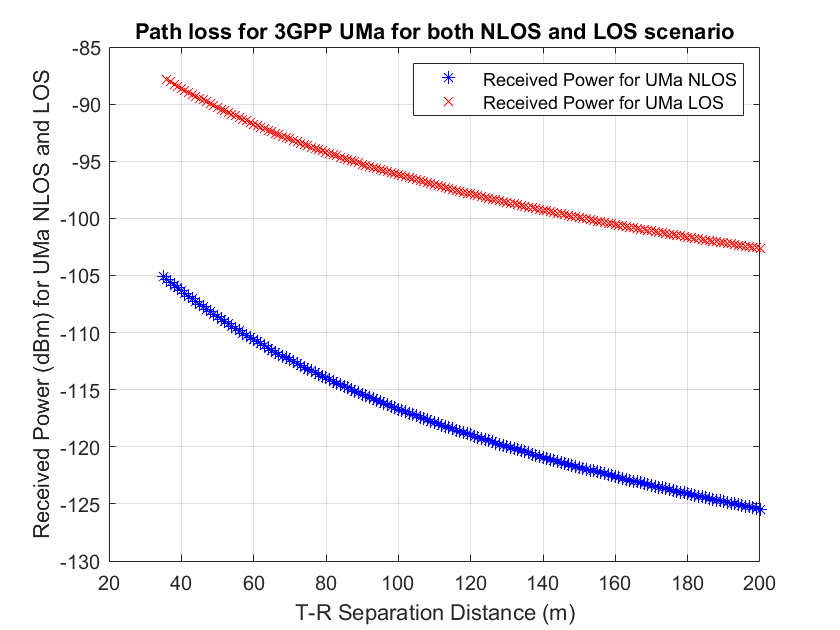

clear;
clc;
close all;

%%step 1 & 3 : General parameters
c = 3e8;              %% speed of light 
f= 28;                %% carier frequncy
f2=40; f3=60;
lamda = c/(f*1e9);    %% wave length
bw=800e6;             %% RF bandwidth 
isd=500;              %% interSiteDist (cell layout)
hbs = 25;             %% BS hight UMa
hut=1.5;              %% hight user terminal hight UMa
min_d2D=35;           %% Minimum Distance between Bs_Ut
max_d2D=200;          %% Maximum Distance between Bs_Ut
user_speed=3*1000/3600; %% user terminal mobility im m/s
P_Tx=35;              % Transmitted power dBm
phi_AOA=10;           % azimoth angle of arrival
phi_AOD=10;           % azimoth angle of departure
theta_ZOA=10;         % zenith angle or arrival
theta_ZOD=10;         % zenith angle or departure
Tx_G=25;              % transmitter gain in dB 
Rx_G=25;              % % transmitter gain in dB
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Step2 Pathloss model
 %% LOS & NLOS
 %% LOS Probabiltity  should add details for variant hut
 %% since hut= 1.5 < 13  so c'=0 page27
 
for i= min_d2D:max_d2D  %% min d2D to max d2D
   
        d3D(i)=sqrt(((hbs-hut)^2)+(i)^2);
        PL_LOS(i)=28+(22*log10(d3D(i)))+(20*log10(f))+30; % +30 to convert to dBm
        %PL_LOS_F2(i)=28+(22*log10(d3D(i)))+(20*log10(f2));
        %PL_LOS_F3(i)=28+(22*log10(d3D(i)))+(20*log10(f3));
        P_Rx_LOS(i)=P_Tx-PL_LOS(i);
        %P_Rx_LOS_F2(i)=P_Tx-PL_LOS(i);
        %P_Rx_LOS_F3(i)=P_Tx-PL_LOS(i);
        PL_NLOS(i)=32.4+(20*log10(f))+(30*log10(d3D(i)))+30; % +30 to convert to dBm
        P_Rx_NLOS(i)=P_Tx-PL_NLOS(i);
        Pr_LOS(i)=((18/i)+exp((-i)/63)*(1-(18/(i)))); %Propability 
        figure(1)
        plot((i),PL_LOS(i),'xr');
%         plot((i),PL_LOS_F2(i),'xr');
%         plot((i),PL_LOS_F3(i),'xr');
        plot((i),PL_NLOS(i),'*b');
        hold on;
        grid on;
        ylabel('Path Loss (dB) for UMa NLOS and LOS');
        xlabel('T-R Separation Distance (m)');
        legend('Pathloss for UMa NLOS','Pathloss for UMa LOS');
        title('Path loss for 3GPP UMa for both NLOS and LOS scenario')
        figure(2)
        plot((i),Pr_LOS(i),'+g')
        hold on;
        grid on;
        ylabel('LOS Probability');
        xlabel('T-R Separation Distance (m)');
        title('LOS Probability for Urban Macro');
        figure(3)
        plot((i),P_Rx_LOS(i),'xr');
        plot((i),P_Rx_NLOS(i),'*b');
        hold on;
        grid on;
        ylabel('Received Power (dBm) for UMa NLOS and LOS');
        xlabel('T-R Separation Distance (m)');
        legend('Received Power for UMa NLOS','Received Power for UMa LOS');
        title('Path loss for 3GPP UMa for both NLOS and LOS scenario')
      
end

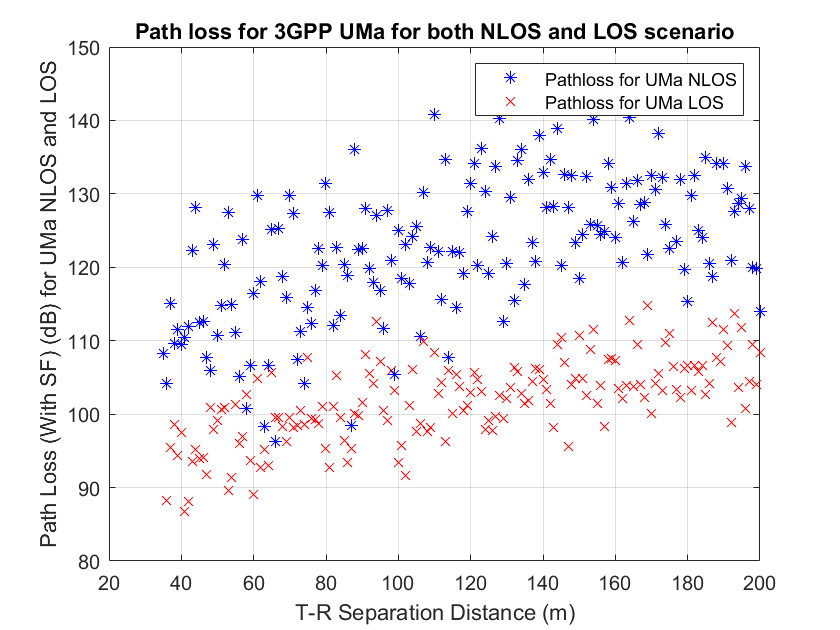

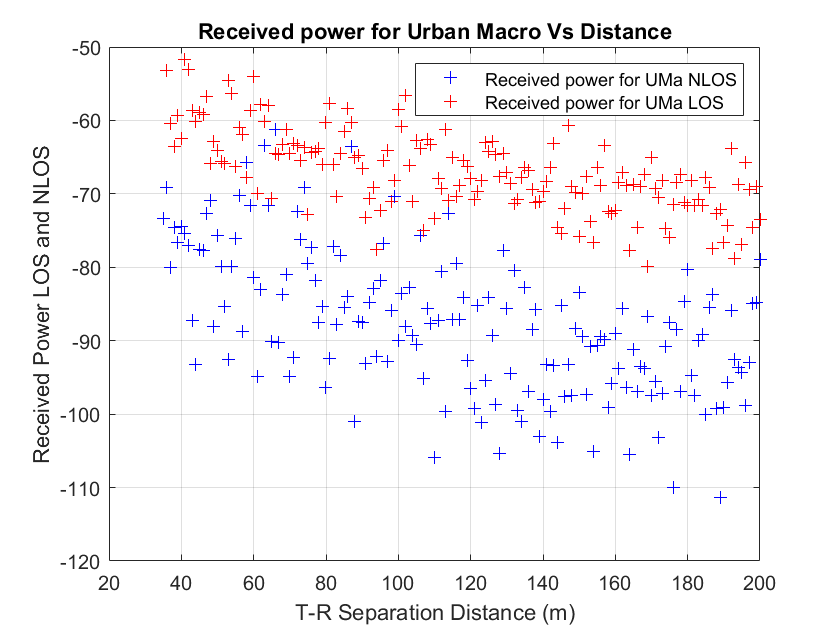

 
      
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

%%step 4 Fast fading model Large scale parameter table 7.5.6
%% LOS UMa
 d3D_random_dist=(d3D(randi([min_d2D max_d2D])));
 meoDS_LOS=-6.955-(0.0963*log10(f));  % mean value of 10-base log of delay spread
 segmaDS_LOS=0.66;                    % standard deviation of 10-bas log of delay spread
 meoASD_LOS=1.06+(0.1114*log10(f));   % mean value of 10-base log of Azimuth angle spread of departure
 segmaASD_LOS=0.28;                   % standard deviation of 10-base log of Azimuth angle spread of departure
 meoASA_LOS=1.81;                     % Mean vlue  of 10-base log of azimuth angle spread of arrival.
 segmaASA_LOS=0.20;                   % standard deviation of 10-base log of azimuth angle spread of arrival.
 meoZSA_LOS=0.95;                     % Mean vlue  of 10-base log of zenith angle spread of arrival.
 segmaZSA_LOS=0.16;                   % standard deviation  of 10-base log of zenith angle spread of arrival
 meoZSD_LOS=max(-0.5,(-2.1*(max_d2D/1000)-0.01*(hut-1.5)+0.75)); % Mean vlue  of 10-base log of zenith angle spread of departure.
 segmaZSD_LOS=0.40;                   % standard deviation  of 10-base log of zenith angle spread of departure
 meoZOD_offset_LOS=0;                 %----------------
 segmaSF_LOS=4;                       % standard deviation  of shadow fading
 meoK=9;                              % Mean vlue  of K-factor            
 segmaK=3.5;                          % standard deviation  of K-factor
 r_tao_LOS=2.5;                       % Delay scaling parameter r.tao
 meoXPR_LOS=8;                        %% ????
 segmaXPR_LOS=4;                      %% ????
 N_LOS=12;                            % Number of clusters
 M_LOS=20;                            % Number of rays per cluster
 C_DS_LOS= max(0.25, 6.5622-(3.4084*log10(f)));  %Cluster DS in (ns)
 C_ASD_LOS=5;                         % Cluster ASD (azimuth angle spread of departure) in [deg]
 C_ASA_LOS=11;                        % Cluster ASA (azimuth angle spread of arrival) in [deg]
 C_ZSA_LOS=7;                         % Cluster ZSA (zenith angle spread of arrival) in [deg]
 meo_ZSD_LOS=max(-0.21,(-14.8*(d3D_random_dist/1000)+0.01*abs(hut-hbs)+0.83));
 C_ZSD_LOS=(3/8)*10^(meo_ZSD_LOS);
 segma_Zeta=3;                        % Per cluster shadowing standard deviation Aeta [dB] for both LOS nNLOS
 
 Mt_LOS=(4*0.5*C_DS_LOS*bw);
 M_AOD_LOS=4*0.5*C_ASD_LOS*((pi*1)/(180*lamda));
 M_ZOD_LOS=4*0.5*C_ZSD_LOS*((pi*1)/(180*lamda));
 M_LOS_Calc=min(max((Mt_LOS*M_AOD_LOS*M_ZOD_LOS),20),M_LOS);

 %% NLOS
 meoDS_NLOS=-6.28-(0.204*log10(f));   % mean value of 10-base log of delay spread
 segmaDS_NLOS=0.39;                   % standard deviation of 10-bas log of delay spread
 meoASD_NLOS=1.5-(0.1144*log10(f));   % mean value of 10-base log of Azimuth angle spread of departure
 segmaASD_NLOS=0.28;                  % standard deviation of 10-base log of Azimuth angle spread of departure
 meoASA_NLOS=2.08-(0.27*log10(f));    % Mean vlue  of 10-base log of azimuth angle spread of arrival.
 segmaASA_NLOS=0.11;                  % standard deviation of 10-base log of azimuth angle spread of arrival.
 meoZSA_NLOS=1.512-(0.3236*log10(f)); % Mean vlue  of 10-base log of zenith angle spread of arrival.
 segmaZSA_NLOS=0.16;                  % standard deviation  of 10-base log of zenith angle spread of arrival
 meoZSD_NLOS=max(-0.5,(-2.1*(max_d2D/1000)-0.01*(hut-1.5)+0.9));  % Mean vlue  of 10-base log of zenith angle spread of departure.
 segmaZSD_NLOS=0.49;                  % standard deviation  of 10-base log of zenith angle spread of departure
 a_fc=(0.208*log10(f))-0.782;           %  STEP 7
 b_fc=25;                               %% STEP 7
 c_fc=(-0.13*log10(f))+2.03;            %% STEP 7
 e_fc=(7.66*log10(f))-5.96;             %  STEP 7 
 meo_offset_ZOD_NLOS=e_fc-(10^(a_fc*log10(max(b_fc,max_d2D))+c_fc-0.07*(hut-1.5)));  % STEP 7
 
 segmaSF_NLOS=7.8;                    % standard deviation  of shadow fading
                                      % segmaSF_NLOS_OPtional=7.8; %% shadow fading std dB 
 r_tao_NLOS=2.3;                      % Delay scaling parameter r.tao
 meoXPR_NLOS=7;                       %% Cross polarization ratio
 segmaXPR_NLOS=3;                     %% ????
 N_NLOS=20;                           % Number of clusters
 M_NLOS=20;                           % Number of rays per cluster
 C_DS_NLOS= max(0.25, 6.5622-(3.4084*log10(f)));  %Cluster DS in (ns)
 C_ASD_NLOS=2;                        % Cluster ASD (azimuth angle spread of departure) in [deg]
 C_ASA_NLOS=15;                       % Cluster ASA (azimuth angle spread of arrival) in [deg]
 C_ZSA_NLOS=7;                        % Cluster ZSA (zenith angle spread of arrival) in [deg]
 meo_ZSD_NLOS=max(-0.5,(-3.1*(d3D_random_dist/1000)+0.01*max(hut-hbs,0)+0.2));
 C_ZSD_NLOS=(3/8)*10^(meo_ZSD_NLOS);
 
 Mt_NLOS=(4*0.5*C_DS_NLOS*bw);
 M_AOD_NLOS=4*0.5*C_ASD_NLOS*((pi*1)/(180*lamda));
 M_ZOD_NLOS=4*0.5*C_ZSD_NLOS*((pi*1)/(180*lamda));
 M_NLOS_Calc=min(max((Mt_NLOS*M_AOD_NLOS*M_ZOD_NLOS),20),M_NLOS);

 % Received power    % Considered P_Tx=35 dBm
 % los & NLOS 
 
 for i= min_d2D:max_d2D               %% min d2D to max d2D
        d3D(i)=sqrt(((hbs-hut)^2)+(i)^2);
        PL_LOS_Abs(i)=28+(22*log10(d3D(i)))+(20*log10(f))+(segmaSF_LOS*randn);   % path loss with adding SF
        P_Rx_LOS_SF(i)=P_Tx-PL_LOS_Abs(i);
        
        PL_NLOS_Abs(i)=32.4+(20*log10(f))+(30*log10(d3D(i)))+(segmaSF_NLOS*randn);  % path loss with adding SF
        P_Rx_NLOS_SF(i)=P_Tx-PL_NLOS_Abs(i);
        figure(4)
        plot((i),PL_LOS_Abs(i),'xr');
        plot((i),PL_NLOS_Abs(i),'*b');
        hold on;
        grid on;
        ylabel('Path Loss (With SF) (dB) for UMa NLOS and LOS');
        xlabel('T-R Separation Distance (m)');
        legend('Pathloss for UMa NLOS','Pathloss for UMa LOS');
        title('Path loss for 3GPP UMa for both NLOS and LOS scenario')
        figure(5)
        plot((i),P_Rx_LOS_SF(i),'+r')
        plot((i),P_Rx_NLOS_SF(i),'+b')
        hold on;
        grid on;
        ylabel('Received Power LOS and NLOS');
        xlabel('T-R Separation Distance (m)');
        legend('Received power for UMa NLOS','Received power for UMa LOS');
        title('Received power for Urban Macro Vs Distance');
 end

 

  
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

 %%Step 5: Cluster delays (page 32)

 %LOS
 X_LOS=rand(1,N_LOS);
 for n=1:N_LOS
      tao_dash_n_LOS(n)=-(r_tao_LOS)*(segmaDS_LOS)*(log(X_LOS(n)));
 end
 for n=1:N_LOS
     tao_n_LOS(n)=(tao_dash_n_LOS(n))-(min(tao_dash_n_LOS));
 end
 tao_n_LOS=sort(tao_n_LOS);  % Cluster Delay
 C_tao=0.7705+(0.0433*meoK)+(0.0002*(meoK^2))+(0.000017*(meoK^3));
 tao_scaled_n_LOS(n)=(tao_n_LOS(n)/C_tao); 
 
 % Delay for each ray in cluster   %% nano sec
 
 for n=1:N_LOS
     for m=1:M_LOS
          tao_nm_LOS_double_prime(n,m)=(rand*(2*C_DS_LOS));
     end
 end
 
  for n=1:N_LOS
     for m=1:M_LOS
          tao_nm_LOS_prime(n,m)=tao_nm_LOS_double_prime(n,m)-min(tao_nm_LOS_double_prime(n,:));
     end
  end
 
  
  for n=1:N_LOS
     for m=1:M_LOS
          tao_nm_LOS(n,m)=tao_n_LOS(n)+tao_nm_LOS_prime(n,m);
     end
  end
  
 %NLOS Cluster Delay
 X_NLOS=rand(1,N_NLOS);
 for k=1:N_NLOS
     tao_dash_n_NLOS(k)=-(r_tao_NLOS)*(segmaDS_NLOS)*(log(X_NLOS(k)));   
 end
 for k=1:N_NLOS
      tao_n_NLOS(k)=(tao_dash_n_NLOS(k))-(min(tao_dash_n_NLOS));
 end

 tao_n_NLOS=sort(tao_n_NLOS);

  % Delay for each ray in cluster   %% nano sec
 for n=1:N_NLOS
     for m=1:M_NLOS
          tao_nm_NLOS_double_prime(n,m)=(rand*(2*C_DS_NLOS));
     end
 end
 
  for n=1:N_NLOS
     for m=1:M_NLOS
          tao_nm_NLOS_prime(n,m)=tao_nm_NLOS_double_prime(n,m)-min(tao_nm_NLOS_double_prime(n,:));
     end
  end
 
  
  for n=1:N_NLOS
     for m=1:M_NLOS
          tao_nm_NLOS(n,m)=tao_n_NLOS(n)+tao_nm_NLOS_prime(n,m);
     end
  end
  
 
    % Propagtion time delay  t0
    % t = distance / speed = d3D /c*1e9
  
   t0=(d3D_random_dist/(3*10^8))*(10^9);  % nano SEC the propagation time for the first arrived element in cluster 1
    
   PL_NLOS_random_distance=32.4+(20*log10(f))+(30*log10(d3D_random_dist))+(segmaSF_NLOS*randn);  % path loss with adding SF
   P_Rx_NLOS_random_distance=10^((P_Tx-PL_NLOS_random_distance)/10);  %In mWatt
   P_Rx_NLOS_random_distance_dBm=P_Tx-PL_NLOS_random_distance;
   direct_P_Rx_NLOS_random_distance_dBm=P_Tx+Tx_G+Rx_G-PL_NLOS_random_distance;
   direct_P_Rx_NLOS_random_distance_mw=10^(direct_P_Rx_NLOS_random_distance_dBm/10)

direct_P_Rx_NLOS_random_distance_mw = 8.1850e-05

   PL_LOS_random_distance=28+(22*log10(d3D_random_dist))+(20*log10(f))+(segmaSF_LOS*randn);   % path loss with adding SF
   P_Rx_LOS_random_distance=10^((P_Tx-PL_LOS_random_distance)/10);  %In mWatt
   P_Rx_LOS_random_distance_dBm=P_Tx-PL_LOS_random_distance;
   direct_P_Rx_LOS_random_distance_dBm=P_Tx+Tx_G+Rx_G-PL_LOS_random_distance; 
   direct_P_Rx_LOS_random_distance_mw=10^(direct_P_Rx_LOS_random_distance_dBm/10)

direct_P_Rx_LOS_random_distance_mw = 0.0328

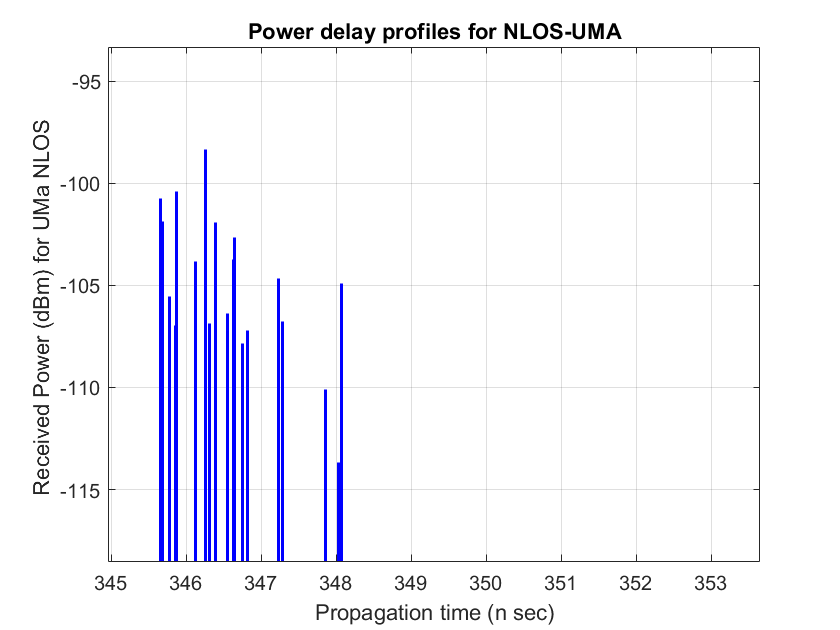

   %% total propagation time for each rays in a one cluster
    %% LOS
   for n=1:N_LOS
       t_n_los(n)=t0+tao_n_LOS(n);
     for m=1:M_LOS
      t_nm_LOS(n,m)=t0+tao_n_LOS(n)+tao_nm_LOS(n,m);
     end
   end
   
   %% NLOS
   for n=1:N_NLOS
       t_n_Nlos(n)=t0+tao_n_NLOS(n);
     for m=1:M_NLOS
      t_nm_NLOS(n,m)=t0+tao_n_NLOS(n)+tao_nm_NLOS(n,m);
     end
   end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%step 6: Generate Cluster power
%LOS



for n=1:N_LOS
    Zn(n)=normrnd(0,3);
     Pn_dash_LOS(n)=exp(-(tao_n_LOS(n))*((r_tao_LOS)-1)/(r_tao_LOS*segmaDS_LOS))*10^(-Zn(n)/10);
 end
 
  P1_LOS=meoK/(meoK+1);
  
  z=zeros(1,N_LOS);
         for n=1:N_LOS
         x(n)=((n)-1);
         if x(n)==0
             z(n)=1;  %Dirac Delta function
         end
     end
    % stem(x,z);

    %% Cluster power in mW we convert it to dbm by 10*log(mW)
    y1=sum(Pn_dash_LOS);
     for n=1:N_LOS
         Pn_LOS_mW(n)=(((1/(meoK+1))*((Pn_dash_LOS(n))/y1)+(z(n)* P1_LOS))*P_Rx_NLOS_random_distance); %Normalized cluster power LOS in mW
         Pn_LOS_dBm(n)=10*log10(Pn_LOS_mW(n)); %Normalized cluster power LOS in dBm
         direct_Pn_LOS_mW(n)=(((1/(meoK+1))*((Pn_dash_LOS(n))/y1)+(z(n)* P1_LOS))*direct_P_Rx_LOS_random_distance_mw);
         direct_Pn_LOS_dBm(n)=10*log10(direct_Pn_LOS_mW(n));
     end
     

 %NLOS
 for n=1:N_NLOS 
     Zn(n)=normrnd(0,3);
     Pn_dash_NLOS(n)=exp(-(tao_n_NLOS(n))*((r_tao_NLOS)-1)/(r_tao_NLOS*segmaDS_LOS))*10^(-Zn(n)/10);
 end
 
 y2=sum(Pn_dash_NLOS);
 
 %% Cluster power in mW we convert it to dbm by 10*log(mW)
 for n=1:N_NLOS
     Pn_NLOS_mW(n)=((Pn_dash_NLOS(n)/y2)*(P_Rx_NLOS_random_distance));  %% Normalized cluster power in mW
     Pn_NLOS_dBm(n)=10*log10(Pn_NLOS_mW(n)); 
     direct_Pn_NLOS_mW(n)=((Pn_dash_NLOS(n)/y2)*(direct_P_Rx_NLOS_random_distance_mw));
     direct_Pn_NLOS_dBm(n)=10*log10(direct_Pn_NLOS_mW(n));
 end
 
 
 %% Power of each ray within a cluster equals Pn,m = Pn/M
 t=[1 -1];
 for n=1:N_NLOS
     for m=1:M_NLOS
         alpha_nm_AOA(n,m)=rand*(2*t(randi(numel(t))));
         alpha_nm_AOD(n,m)=rand*(2*t(randi(numel(t))));
         alpha_nm_ZOA(n,m)=rand*(2*t(randi(numel(t))));
         alpha_nm_ZOD(n,m)=rand*(2*t(randi(numel(t))));
     end
 end
 
 %LOS
 for n=1:N_LOS
     for m=1:M_LOS
          P_nm_LOS_Prime=(exp(-tao_nm_LOS_prime/C_DS_LOS))*(exp(-sqrt(2)*abs(alpha_nm_AOA(n,m))/C_ASA_LOS))*(exp(-sqrt(2)*abs(alpha_nm_AOD(n,m))/C_ASD_LOS))*(exp(-sqrt(2)*abs(alpha_nm_ZOA(n,m))/C_ZSA_LOS))*(exp(-sqrt(2)*abs(alpha_nm_ZOD(n,m))/C_ZSD_LOS));
     end
 end
 
 for n=1:N_LOS
     for m=1:M_LOS
   P_nm_LOS_mW(n,m)=Pn_LOS_mW(n)*((P_nm_LOS_Prime(n,m))/(sum(P_nm_LOS_Prime(n,:))));
   P_nm_LOS_dBm(n,m)=10*log10(P_nm_LOS_mW(n,m)); % power im mW
     end
 end
 
   
   %NLOS
  for n=1:N_NLOS
     for m=1:M_NLOS
          P_nm_NLOS_Prime=(exp(-tao_nm_NLOS_prime/C_DS_NLOS))*(exp(-sqrt(2)*abs(alpha_nm_AOA(n,m))/C_ASA_NLOS))*(exp(-sqrt(2)*abs(alpha_nm_AOD(n,m))/C_ASD_NLOS))*(exp(-sqrt(2)*abs(alpha_nm_ZOA(n,m))/C_ZSA_NLOS))*(exp(-sqrt(2)*abs(alpha_nm_ZOD(n,m))/C_ZSD_NLOS));
     end
 end
 
 for n=1:N_NLOS
     for m=1:M_NLOS
   P_nm_NLOS_mW(n,m)=Pn_NLOS_mW(n)*((P_nm_NLOS_Prime(n,m))/(sum(P_nm_NLOS_Prime(n,:))));
   P_nm_NLOS_dBm(n,m)=10*log10(P_nm_NLOS_mW(n,m)); % power im dBm
     end
 end
 
 figure(6)
  for n=1:N_NLOS
      stem(t_n_Nlos(n),Pn_NLOS_dBm(n),'BaseValue',min(Pn_NLOS_dBm),'LineStyle','-','Marker','none','linewidth',1.5,'color',[0 0 1]);
      xlim([0.998*min(t_n_Nlos) 1.01*max(t_n_Nlos)]); 
      ylim([min(Pn_NLOS_dBm) max(Pn_NLOS_dBm)+5]);
      ylabel('Received Power (dBm) for UMa NLOS ');
      xlabel('Propagation time (n sec)');
      title('Omni-directional Power delay profiles for NLOS-UMA')
      hold on;
      grid on;
  end

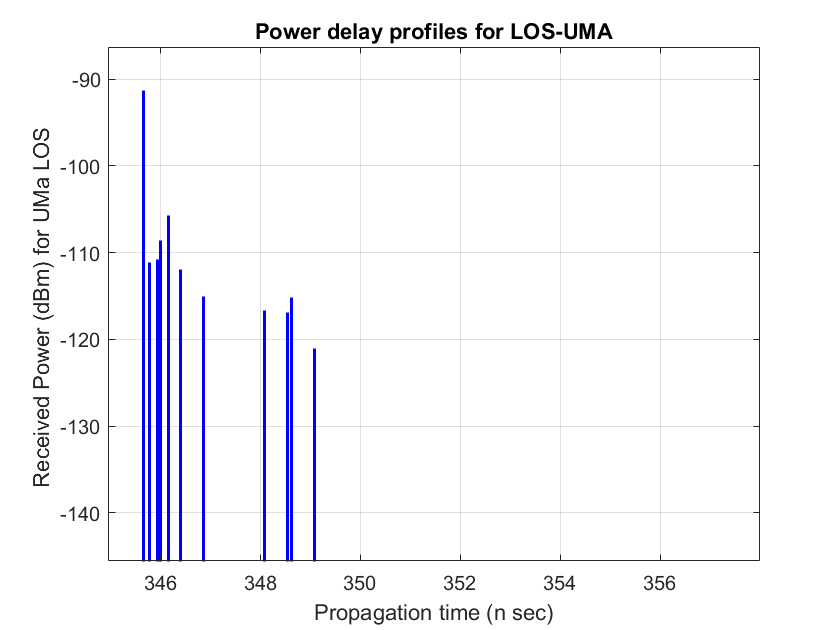


  figure(7)
  for n=1:N_LOS
      stem(t_n_los(n),Pn_LOS_dBm(n),'BaseValue',min(Pn_LOS_dBm),'LineStyle','-','Marker','none','linewidth',1.5,'color',[0 0 1]);
      xlim([0.998*min(t_n_los) 1.01*max(t_n_los)]); 
      ylim([min(Pn_LOS_dBm) max(Pn_LOS_dBm)+5]);
      ylabel('Received Power (dBm) for UMa LOS ');
      xlabel('Propagation time (n sec)');
      title('Omi-directional Power delay profiles for LOS-UMA')
      hold on;
      grid on;
  end

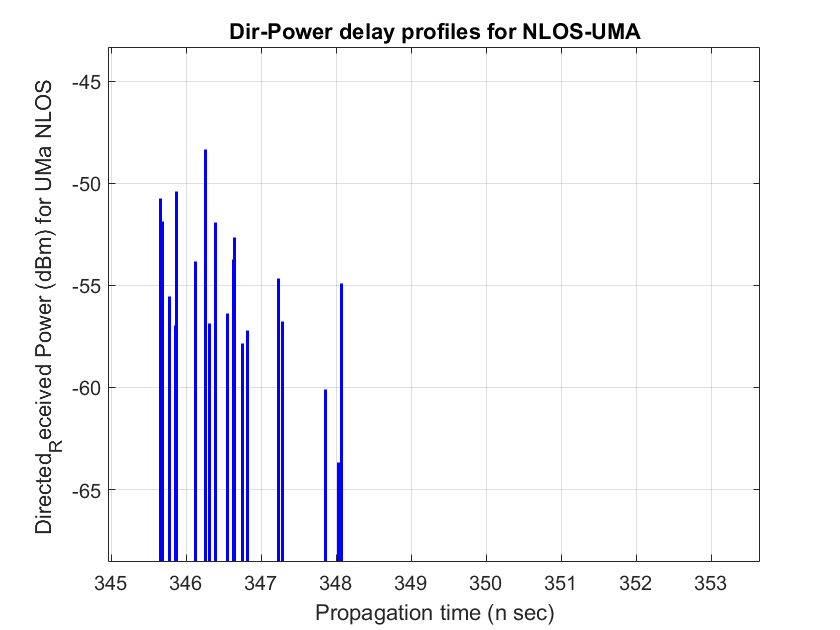

  
  figure(8)
  for n=1:N_NLOS
      stem(t_n_Nlos(n),direct_Pn_NLOS_dBm(n),'BaseValue',min(direct_Pn_NLOS_dBm),'LineStyle','-','Marker','none','linewidth',1.5,'color',[0 0 1]);
      xlim([0.998*min(t_n_Nlos) 1.01*max(t_n_Nlos)]); 
      ylim([min(direct_Pn_NLOS_dBm) max(direct_Pn_NLOS_dBm)+5]);
      ylabel('Directed_Received Power (dBm) for UMa NLOS ');
      xlabel('Propagation time (n sec)');
      title('Dir-Power delay profiles for NLOS-UMA')
      hold on;
      grid on;
  end

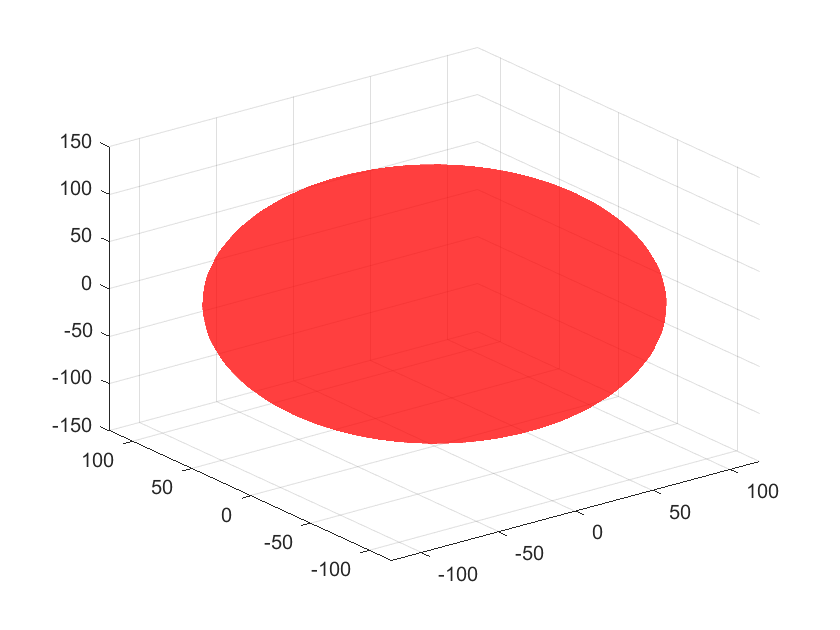

  
  
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
%%Step 7 Generate arrival and departure Angels for azimuth and elevation:
 
 %%----------Azimoth Angles of Arrival AOA-----------%%

 %%Scaling factor 
  %NLOS        
  
 %C_phi_NLOS=[0 0 0 0.779 0.860 0 0 1.018 0 1.090 1.123 1.146 0 1.190 1.211 1.226 0 0 1.273 1.289];
 C_phi_NLOS=1.289;
 for i=1:N_NLOS
     phi_n_dash_AOA_NLOS(i)=(2*(segmaASA_NLOS/1.4)*(sqrt(-log(Pn_NLOS_mW(i)/max(Pn_NLOS_mW)))))/(C_phi_NLOS);
 end
 
  %LOS
 K_Con_Azimoth=((1.1035)-(0.028*meoK)-(0.002*(meoK^2))+(0.0001*(meoK^3)));
   for i=1:N_LOS    %number of cluster in LOS is 12
     C_phi_LOS=(1.146)*K_Con_Azimoth;
     phi_n_dash_AOA_LOS(i)=(2*(segmaASA_LOS/1.4)*(sqrt(-log(Pn_LOS_mW(i)/max(Pn_LOS_mW)))))/(C_phi_LOS);
   end
  
 
 %NLOS   
t=[1 -1];
 for i=1:N_NLOS
     x_random_var(i)=t(randi(numel(t)));            % random value for x= 1 or -1
     y_random_var_Azimoth_Arr_NLOS(i)=normrnd(0,(segmaASA_NLOS/7)^2);
     phi_n_AOA_NLOS(i)=((x_random_var(i)*phi_n_dash_AOA_NLOS(i))+y_random_var_Azimoth_Arr_NLOS(i)+(phi_AOA*pi/180));
 end
 
 %LOS  
 for i=1:N_LOS
    y_random_var_Azimoth_Arr_LOS(i)=normrnd(0,(segmaASA_LOS/7)^2);
    phi_n_AOA_LOS(i)=((x_random_var(i)*phi_n_dash_AOA_LOS(i))+y_random_var_Azimoth_Arr_LOS(i))-((x_random_var(1)*phi_n_dash_AOA_LOS(1))+y_random_var_Azimoth_Arr_LOS(1)-(phi_AOA*pi/180)); 
 end
 
 % Add offset angles 
 %LOS
 alpha_m=[0.0447 -0.0477 0.1413 -0.1413 0.2492 -0.2492 0.3715 -0.3715 0.5129 -0.5129 0.6797 -0.6797 0.8844 -0.8844 1.1481 -1.1481 1.5191 -1.5195 2.1551 -2.1551];
 for n=1:N_LOS
     for m=1:M_LOS
          phi_nm_AOA_LOS(n,m)=phi_n_AOA_LOS(n)+C_ASA_LOS*alpha_m(m);
     end
 end
%NLOS
 for n=1:N_NLOS
     for m=1:M_NLOS
          phi_nm_AOA_NLOS(n,m)=phi_n_AOA_NLOS(n)+C_ASA_NLOS*alpha_m(m);
     end
 end
 
 %%----------Azimoth Angles of Departure AOD-----------%%
  
 %%Scaling factor 
 %NLOS       
 %C_phi_NLOS=[0 0 0 0.779 0.860 0 0 1.018 0 1.090 1.123 1.146 0 1.190 1.211 1.226 0 0 1.273 1.289];
 for i=1:N_NLOS
     phi_dash_AOD_NLOS(i)=(2*(segmaASD_NLOS/1.4)*(sqrt(-log(Pn_NLOS_mW(i)/max(Pn_NLOS_mW)))))/(C_phi_NLOS);
 end
 
  %LOS  
 K_Con=((1.1035)-(0.028*meoK)-(0.002*(meoK^2))+(0.0001*(meoK^3)));
   for i=1:N_LOS    %number of cluster in LOS is 12
     C_phi_LOS=(C_phi_NLOS)*K_Con;
     phi_dash_AOD_LOS(i)=(2*(segmaASD_LOS/1.4)*(sqrt(-log(Pn_LOS_mW(i)/max(Pn_LOS_mW)))))/(C_phi_LOS);
   end
   
   %NLOS  
   for i=1:N_NLOS
     y_random_var_Azimoth_Arr_NLOS(i)=normrnd(0,(segmaASD_NLOS/7)^2);
     phi_n_AOD_NLOS(i)=((x_random_var(i)*phi_dash_AOD_NLOS(i))+y_random_var_Azimoth_Arr_NLOS(i)+(phi_AOD*pi/180));
   end
 
 %LOS  
 for i=1:N_LOS
    y_random_var_Azimoth_Dep_LOS(i)=normrnd(0,(segmaASD_LOS/7)^2);
    phi_n_AOD_LOS(i)=((x_random_var(i)*phi_dash_AOD_LOS(i))+y_random_var_Azimoth_Dep_LOS(i))-((x_random_var(i)*phi_dash_AOD_LOS(1))+y_random_var_Azimoth_Dep_LOS(i)-(phi_AOD*pi/180)); 
 end
 
 % Add offset angles 
 %LOS
 alpha_m=[0.0447 -0.0477 0.1413 -0.1413 0.2492 -0.2492 0.3715 -0.3715 0.5129 -0.5129 0.6797 -0.6797 0.8844 -0.8844 1.1481 -1.1481 1.5191 -1.5195 2.1551 -2.1551];
 for n=1:N_LOS
     for m=1:M_LOS
          phi_nm_AOD_LOS(n,m)=phi_n_AOD_LOS(n)+C_ASD_LOS*alpha_m(m);
     end
 end
%NLOS
 for n=1:N_NLOS
     for m=1:M_NLOS
          phi_nm_AOD_NLOS(n,m)=phi_n_AOD_NLOS(n)+C_ASD_NLOS*alpha_m(m);
     end
 end 

 %----------------------------------------------------------------------------------------------------------------------%
 
 %%----------Zineth Angles of Arrival ZOA-----------%%
  %%Scaling factor 
  %NLOS
 %C_theta_NLOS=[0 0 0 0 0 0 0 0.889 0 0.957 1.031 1.104 0 0 1.1088 0 0 0 1.184 1.178];
 C_theta_NLOS=1.178;
 for i=1:N_NLOS
     theta_n_dash_ZOA_NLOS(i)=((-segmaZSA_NLOS)*(log(Pn_NLOS_mW(i)/max(Pn_NLOS_mW))))/(C_theta_NLOS);
 end
 
  %LOS
 K_Con_Zineth=((1.3086)+(0.0339*meoK)-(0.0077*(meoK^2))+(0.0002*(meoK^3)));
 C_theta_LOS=(1.104)*K_Con_Zineth;  
 for i=1:N_LOS    %number of cluster in LOS is 12
         theta_n_dash_ZOA_LOS(i)=((-segmaZSA_LOS)*(log(Pn_LOS_mW(i)/max(Pn_LOS_mW))))/(C_theta_LOS);
 end
  
 
 %NLOS
 %t=[1 -1];
 for i=1:N_NLOS
     %x_random_var(i)=t(randi(numel(t)));            % random value for x= 1 or -1
     y_random_var_Zineth_Arr_NLOS(i)=normrnd(0,(segmaZSA_NLOS/7)^2);
     theta_n_ZOA_NLOS(i)=((x_random_var(i)*theta_n_dash_ZOA_NLOS(i))+y_random_var_Zineth_Arr_NLOS(i)+(theta_ZOA*pi/180));
 end
 
 %LOS
 for i=1:N_LOS
    y_random_var_Zineth_Arr_LOS(i)=normrnd(0,(segmaZSA_LOS/7)^2);
    theta_n_ZOA_LOS(i)=((x_random_var(i)*theta_n_dash_ZOA_LOS(i))+y_random_var_Zineth_Arr_LOS(i))-((x_random_var(i)*theta_n_dash_ZOA_LOS(1))+y_random_var_Zineth_Arr_LOS(i)-(theta_ZOA*pi/180)); 
 end
 
 % Add offset angles 
 %LOS
 %alpha_m=[0.0447 -0.0477 0.1413 -0.1413 0.2492 -0.2492 0.3715 -0.3715 0.5129 -0.5129 0.6797 -0.6797 0.8844 -0.8844 1.1481 -1.1481 1.5191 -1.5195 2.1551 -2.1551];
 for n=1:N_LOS
     for m=1:M_LOS
          theta_nm_ZOA_LOS(n,m)=(theta_n_ZOA_LOS(n)+C_ZSA_LOS*alpha_m(m))*(180/pi);
          if theta_nm_ZOA_LOS(n,m)>180 
             theta_nm_ZOA_LOS(n,m)=360-theta_nm_ZOA_LOS(n,m);
              if theta_nm_ZOA_LOS(n,m)>180 
              theta_nm_ZOA_LOS(n,m)=360-theta_nm_ZOA_LOS(n,m);
                if theta_nm_ZOA_LOS(n,m)>180 
                   theta_nm_ZOA_LOS(n,m)=360-theta_nm_ZOA_LOS(n,m);
          elseif theta_nm_ZOA_LOS(n,m)<-180  
               theta_nm_ZOA_LOS(n,m)=360+theta_nm_ZOA_LOS(n,m);
                 if theta_nm_ZOA_LOS(n,m)<-180 
                     theta_nm_ZOA_LOS(n,m)=360+theta_nm_ZOA_LOS(n,m);
                   if theta_nm_ZOA_LOS(n,m)<-180 
                      theta_nm_ZOA_LOS(n,m)=360+theta_nm_ZOA_LOS(n,m);
                     if theta_nm_ZOA_LOS(n,m)<-180 
                        theta_nm_ZOA_LOS(n,m)=360+theta_nm_ZOA_LOS(n,m);
                         if theta_nm_ZOA_LOS(n,m)<-180 
                           theta_nm_ZOA_LOS(n,m)=360+theta_nm_ZOA_LOS(n,m);
          
                         end
                     end
                   end
                 end
                end
              end
          end
     end
 end
 
%NLOS
 for n=1:N_NLOS
     for m=1:M_NLOS
          theta_nm_ZOA_NLOS(n,m)=(theta_n_ZOA_NLOS(n)+C_ZSA_NLOS*alpha_m(m))*(180/pi);
          if theta_nm_ZOA_NLOS(n,m)>180 && theta_nm_ZOA_NLOS(n,m)<360
             theta_nm_ZOA_NLOS(n,m)=360-theta_nm_ZOA_NLOS(n,m);
          elseif theta_nm_ZOA_NLOS(n,m)>540 && theta_nm_ZOA_NLOS(n,m)<720
              theta_nm_ZOA_NLOS(n,m)=720-theta_nm_ZOA_NLOS(n,m);
          elseif theta_nm_ZOA_NLOS(n,m)>900 && theta_nm_ZOA_NLOS(n,m)<1080
              theta_nm_ZOA_NLOS(n,m)=1080-theta_nm_ZOA_NLOS(n,m);
          elseif theta_nm_ZOA_NLOS(n,m)<-180 && theta_nm_ZOA_NLOS(n,m)>-360 
              theta_nm_ZOA_NLOS(n,m)=360+theta_nm_ZOA_NLOS(n,m);
              elseif theta_nm_ZOA_NLOS(n,m)<-540 && theta_nm_ZOA_NLOS(n,m)>-720
                  theta_nm_ZOA_NLOS(n,m)=720+theta_nm_ZOA_NLOS(n,m);
          end
              
     end
 end
 
  %%----------Zineth Angles of Departure ZOD-----------%%
  %%Scaling factor 
  %NLOS
 %C_theta_NLOS=[0 0 0 0 0 0 0 0.889 0 0.957 1.031 1.104 0 0 1.1088 0 0 0 1.184 1.178];
 for i=1:N_NLOS
     theta_n_dash_ZOD_NLOS(i)=((-segmaZSD_NLOS)*(log(Pn_NLOS_mW(i)/max(Pn_NLOS_mW))))/(C_theta_NLOS);
 end
 
  %LOS
 K_Con_Zineth=((1.3086)+(0.0339*meoK)-(0.0077*(meoK^2))+(0.0002*(meoK^3)));
%  C_theta_LOS=(C_theta_NLOS)*K_Con_Zineth;  
 for i=1:N_LOS    %number of cluster in LOS is 12
          theta_n_dash_ZOD_LOS(i)=((-segmaZSD_LOS)*(log(Pn_LOS_mW(i)/max(Pn_LOS_mW))))/(C_theta_LOS);
 end
  
 
 %NLOS
 %t=[1 -1];
 for i=1:N_NLOS
     %x_random_var(i)=t(randi(numel(t)));            % random value for x= 1 or -1
     y_random_var_Zineth_Dep_NLOS(i)=normrnd(0,(segmaZSD_NLOS/7)^2);
     theta_n_ZOD_NLOS(i)=((x_random_var(i)*theta_n_dash_ZOD_NLOS(i))+y_random_var_Zineth_Dep_NLOS(i)+(theta_ZOD*pi/180)+meo_offset_ZOD_NLOS);
 end
 
 %LOS
 for i=1:N_LOS
    y_random_var_Zineth_Dep_LOS(i)=normrnd(0,(meoZSD_LOS/7)^2);
    theta_n_ZOD_LOS(i)=(x_random_var(i)*theta_n_dash_ZOD_LOS(i))+y_random_var_Zineth_Dep_LOS(i)-((x_random_var(1)*theta_n_dash_ZOD_LOS(1))+y_random_var_Zineth_Dep_LOS(1)-(theta_ZOD*pi/180)); 
 end
 
 % Add offset angles 
 %LOS
 %alpha_m=[0.0447 -0.0477 0.1413 -0.1413 0.2492 -0.2492 0.3715 -0.3715 0.5129 -0.5129 0.6797 -0.6797 0.8844 -0.8844 1.1481 -1.1481 1.5191 -1.5195 2.1551 -2.1551];
 for n=1:N_LOS
     for m=1:M_LOS
          theta_nm_ZOD_LOS(n,m)=theta_n_ZOD_LOS(n)+((3/8)*(10^(meoZSD_LOS))*alpha_m(m));
     end
 end
%NLOS
 for n=1:N_NLOS
     for m=1:M_NLOS
          theta_nm_ZOD_NLOS(n,m)=theta_n_ZOD_NLOS(n)+((3/8)*(10^(meoZSD_NLOS))*alpha_m(m));
     end
 end
 

%%%%%%%%%%%%%%%%%%%%%%%%%%
           
%    polarscatter(phi_n_AOA_NLOS,Pn_NLOS_dBm);
%  figure(8)
%    polarscatter(phi_n_AOA_NLOS*(180/pi),Pn_NLOS_dBm);
%    %polarplot(phi_n_AOA_NLOS*(180/pi),Pn_NLOS_dBm);
%    hold on;
%    grid on;
%    title('AOA power spectrum for NLOS, UMa, F= 28 GHz');
%    
%  figure(9)
%    polarscatter(phi_n_AOA_LOS*(180/pi),Pn_LOS_dBm);
%    hold on;
%    grid on;
%    title('AOA power spectrum for LOS, UMa, F= 28 GHZ');

%%% plot 3D AOA
   figure(10) 
        smallestPower = min(Pn_NLOS_dBm)-1;
        largestPower = max(Pn_NLOS_dBm)-10;
        middlePower = (smallestPower + largestPower)/2;
     
      [xsph, ysph, zsph] = sphere(50);
        r = smallestPower;
       surf(r*xsph,r*ysph,r*zsph,'facealpha',.5,'facecolor',[1 0 0],'edgecolor','none');

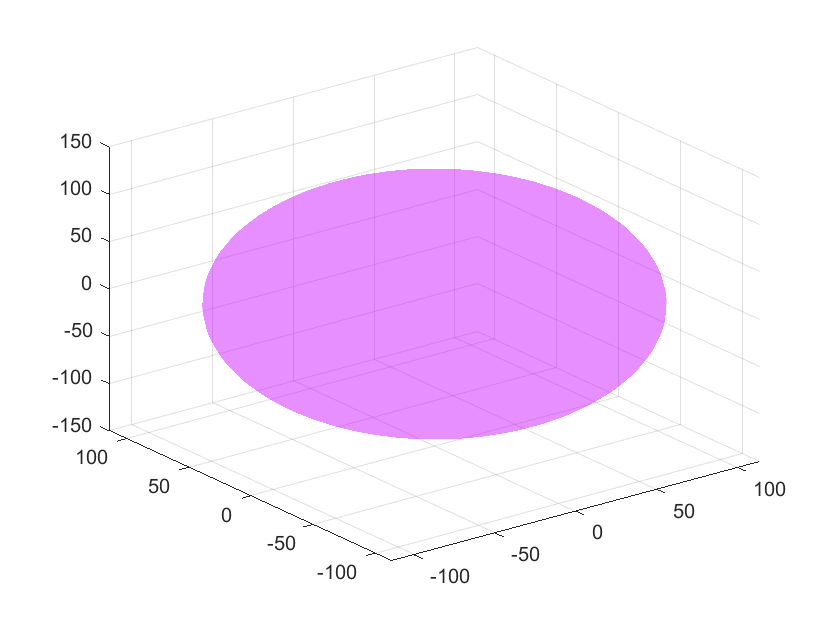

       
     %%% create another spherical surface
    [xsph, ysph, zsph] = sphere(50);
    r_10 = middlePower;
    surf(r_10*xsph,r_10*ysph,r_10*zsph,'facealpha',.25,'facecolor',[0.8 0 1],'edgecolor','none')

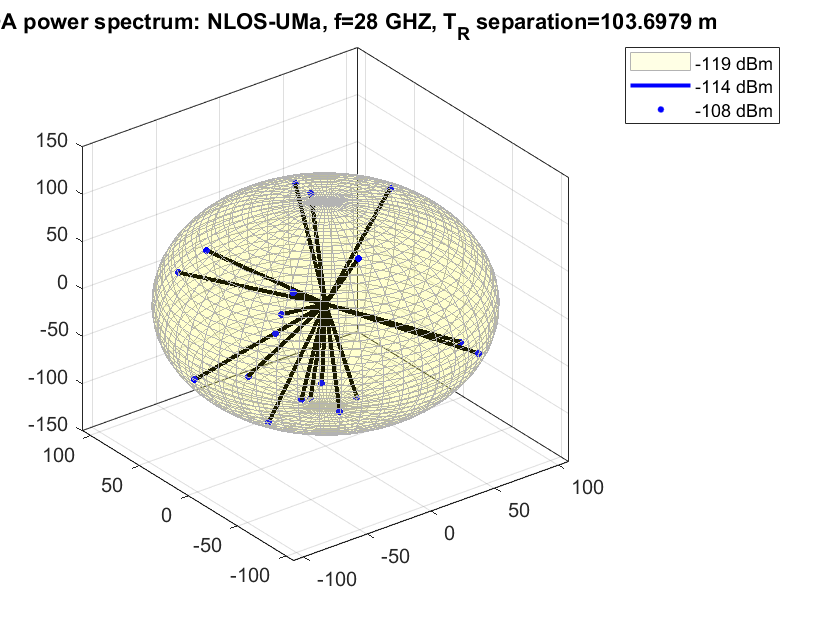

  
     %%% create another spherical surface
    [xsph, ysph, zsph] = sphere(50);
    r_20 = largestPower;
    surf(r_20*xsph,r_20*ysph,r_20*zsph,'facealpha',.1,'facecolor',[1 1 0],'edgecolor',[0.7 0.7 0.7]);
    
    hold on;
    for n=1:N_NLOS
       %%% extract power column
        Pr_plot = Pn_NLOS_dBm(n);

        %%% extract azimuth, and switch to radians
        Azi_plot = phi_n_AOA_NLOS(n)*180/pi;

        %%% extract elevation, and switch to radians
        El_plot = theta_n_ZOA_NLOS(n)*180/pi;

        %%% transform to Cartesian
        [x_plot, y_plot, z_plot] = sph2cart(Azi_plot,El_plot,Pr_plot);
        
       
        %%% plot in 3D
        plot3(x_plot,y_plot,z_plot,'color','b','markersize',10,'linewidth',2);
    
        plot3(x_plot,y_plot,z_plot,'.','color','b','markersize',10,'linewidth',4)
    end
    %N=10
   for n = 1:N_NLOS
        Pr_plot(n) = Pn_NLOS_dBm(n);

        %%% extract azimuth, and switch to radians
        Azi_plot(n) = phi_n_AOA_NLOS(n)*180/pi;

        %%% extract elevation, and switch to radians
        El_plot (n)= theta_n_ZOA_NLOS(n)*180/pi;
        
          
    end
    xa=0; ya=0; za=0;       
    [xx, yy, zz] = sph2cart(Azi_plot,El_plot,Pr_plot);                      
            %%% construct 3-D array of lines connecting power levels on
            %%% at a given azimuth angle
         for n = 1:N_NLOS
            x_array = linspace(xa,xx(n));
            y_array = linspace(ya,yy(n));
            z_array = linspace(za,zz(n));
         
            %%% plot 3-D lines
            plot3(x_array,y_array,z_array,'k','linestyle','-','linewidth',2);
         end
title(['3D-AOA power spectrum: NLOS-UMa, f=28 GHZ, T_R separation=',num2str(d3D_random_dist),' m']);    
box on   
legend([num2str(smallestPower,'%.0f'),' dBm'],[num2str(middlePower,'%.0f'),' dBm'],...
    [num2str(largestPower,'%.0f'),' dBm']);



%%% plot 3D AOD
 figure(11) 
        smallestPower = min(Pn_NLOS_dBm)-1;
        largestPower = max(Pn_NLOS_dBm)-10;
        middlePower = (smallestPower + largestPower)/2;
     
      [xsph, ysph, zsph] = sphere(50);
        r = smallestPower;
       surf(r*xsph,r*ysph,r*zsph,'facealpha',.5,'facecolor',[1 0 0],'edgecolor','none');

       
     %%% create another spherical surface
    [xsph, ysph, zsph] = sphere(50);
    r_10 = middlePower;
    surf(r_10*xsph,r_10*ysph,r_10*zsph,'facealpha',.25,'facecolor',[0.8 0 1],'edgecolor','none')

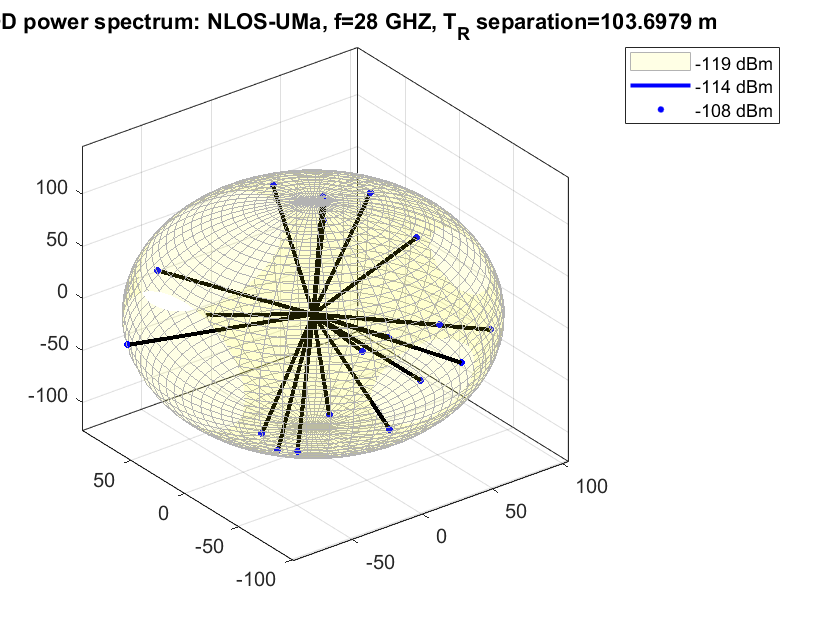

  
     %%% create another spherical surface
    [xsph, ysph, zsph] = sphere(50);
    r_20 = largestPower;
    surf(r_20*xsph,r_20*ysph,r_20*zsph,'facealpha',.1,'facecolor',[1 1 0],'edgecolor',[0.7 0.7 0.7]);
    
    hold on;
    for n=1:N_NLOS
       %%% extract power column
        Pr_plot = Pn_NLOS_dBm(n);

        %%% extract azimuth, and switch to radians
        Azi_plot = phi_n_AOD_NLOS(n)*180/pi;

        %%% extract elevation, and switch to radians
        El_plot = theta_n_ZOD_NLOS(n)*180/pi;

        %%% transform to Cartesian
        [x_plot, y_plot, z_plot] = sph2cart(Azi_plot,El_plot,Pr_plot);
        
       
        %%% plot in 3D
        plot3(x_plot,y_plot,z_plot,'color','b','markersize',10,'linewidth',2);
    
        plot3(x_plot,y_plot,z_plot,'.','color','b','markersize',10,'linewidth',4)
    end
   
   for n = 1:N_NLOS
        Pr_plot(n) = Pn_NLOS_dBm(n);

        %%% extract azimuth, and switch to radians
        Azi_plot(n) = phi_n_AOD_NLOS(n)*180/pi;

        %%% extract elevation, and switch to radians
        El_plot (n)= theta_n_ZOD_NLOS(n)*180/pi;
        
          
    end
    xb=0; yb=0; zb=0;       
    [xx, yy, zz] = sph2cart(Azi_plot,El_plot,Pr_plot);                      
            %%% construct 3-D array of lines connecting power levels on
            %%% at a given azimuth angle
         for n = 1:N_NLOS
            x_array = linspace(xb,xx(n));
            y_array = linspace(yb,yy(n));
            z_array = linspace(zb,zz(n));
         
            %%% plot 3-D lines
            plot3(x_array,y_array,z_array,'k','linestyle','-','linewidth',2);
         end
 title(['3D-AOD power spectrum: NLOS-UMa, f=28 GHZ, T_R separation=',num2str(d3D_random_dist),' m']);
     
box on    
legend([num2str(smallestPower,'%.0f'),' dBm'],[num2str(middlePower,'%.0f'),' dBm'],...
    [num2str(largestPower,'%.0f'),' dBm']);



            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 % Step 8 Coupling of rays within a cluster Azimoth and Elevation
 % LOS
   
 [a h_LOS]=sort(rand(N_LOS,M_LOS*1),1);       % create N*NumLinks random permutations of integers [1:M]
 inds = h_LOS+repmat([1:N_LOS:N_LOS*M_LOS*1],N_LOS,1)-1;       
 
 % Couple randomly AOD to AOA angles within a cluster
 phi_nm_AOD_LOS_paired = phi_nm_AOD_LOS(inds);  
 phi_nm_AOA_LOS_paired = phi_nm_AOA_LOS(inds);
 
 % Couple randomly ZOD to ZOA angles within a cluster
 theta_nm_ZOD_LOS_paired = theta_nm_ZOD_LOS(inds);
 theta_nm_ZOA_LOS_paired = theta_nm_ZOA_LOS(inds);
 
 %% NLOS
  [b, h_NLOS]= sort(rand(N_NLOS,M_NLOS*1),1);                                          
  inds = h_NLOS + repmat([1:N_NLOS:N_NLOS*M_NLOS],N_NLOS,1)-1;
 
 % Couple randomly AOD to AOA angles within a cluster
 phi_nm_AOD_NLOS_paired = phi_nm_AOD_NLOS(inds);  
 phi_nm_AOA_NLOS_paired = phi_nm_AOA_NLOS(inds);
 
 % Couple randomly ZOD to ZOA angles within a cluster
 theta_nm_ZOD_NLOS_paired = theta_nm_ZOD_NLOS(inds);
 theta_nm_ZOA_NLOS_paired = theta_nm_ZOA_NLOS(inds);
 
  
  
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
 % Step 9 Generate cross polarization power ratio
 % LOS
 
 for n=1:N_LOS
     for m=1:M_LOS
         X_nm_LOS(n,m)=normrnd(meoXPR_LOS,segmaXPR_LOS^2);
         K_nm_LOS(n,m)=10^(X_nm_LOS(n,m)/10);
         
     end
 end
 
 % NLOS
 for n=1:N_NLOS
     for m=1:M_NLOS
         X_nm_NLOS(n,m)=normrnd(meoXPR_NLOS,segmaXPR_NLOS^2);
         K_nm_NLOS(n,m)=10^(X_nm_NLOS(n,m)/10);
         
     end
 end
 
 
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  
  % Step 10 draw initial random phases
  z_random_variable=rand(1,M_LOS);
  % LOS
  for n=1:N_LOS
      for m=1:M_LOS
          phases_mn_LOS(n,m)=2*pi*z_random_variable(m);
      end
  end
  
  %NLOS
  for n=1:N_NLOS
      for m=1:M_NLOS
          phases_mn_NLOS(n,m)=2*pi*z_random_variable(m);
      end
  end
  
%  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%    
%   % step 11 Generate channel coefficient 
%   
% %   NumBsElements_U=2          % - Number of BS array antenna elements [ {2} ]
% %   NumMsElements_S=2          %- Number of MS array antenna elements [ {2} ]
% % 
% %  SampleDensity=2             %- number of time samples per half wavelength [ {2} ]
% %  NumTimeSamples=100          %- number of time samples [ {100} ]
% %  DelaySamplingInterval=25e-9 %- delay sampling grid [ {1.6276e-008} ]
% %   MsNumber                  - [1:number of useers]
% %   ThetaBs                   - U(-180,180) degrees, U denotes uniform pdf
% %   ThetaMs                   - U(-180,180) degrees
% %   PhiBs                     - NaN,
% %   PhiMs                     - NaN,
%  %   user_speed=3*1000/3600
% %   MsDirection = u(-180,180);   % degrees with respect to broadside
% 
% 
% 

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Power spectrum array of arrays
index=1;
    for n=1:N_NLOS
        for m=1:M_NLOS
            Pwoerspectrum(:,:,index)=t_nm_NLOS(:,:);
        end
    end
    index=index+1;
    for n=1:N_NLOS
        for m=1:M_NLOS
           Pwoerspectrum(:,:,index)=P_nm_NLOS_mW(:,:);
          
        end
     end
    index=index+1;
     
    for n=1:N_NLOS
        for m=1:M_NLOS
           Pwoerspectrum(:,:,index)=phases_mn_NLOS(:,:);
        end
    end
    index=index+1;
    for n=1:N_NLOS
        for m=1:M_NLOS
           Pwoerspectrum(:,:,index)=phi_nm_AOD_NLOS(:,:);
        end
    end
    
     index=index+1;
     for n=1:N_NLOS
        for m=1:M_NLOS
             Pwoerspectrum(:,:,index)=theta_nm_ZOD_NLOS(:,:);
        end
     end
    
     index=index+1;
     for n=1:N_NLOS
        for m=1:M_NLOS
            Pwoerspectrum(:,:,index)=phi_nm_AOA_NLOS(:,:);
        end
     end
    
     index=index+1;
     for n=1:N_NLOS
        for m=1:M_NLOS
              Pwoerspectrum(:,:,index)=theta_nm_ZOA_NLOS(:,:); 
        end      
    end   

